## Module one project 1

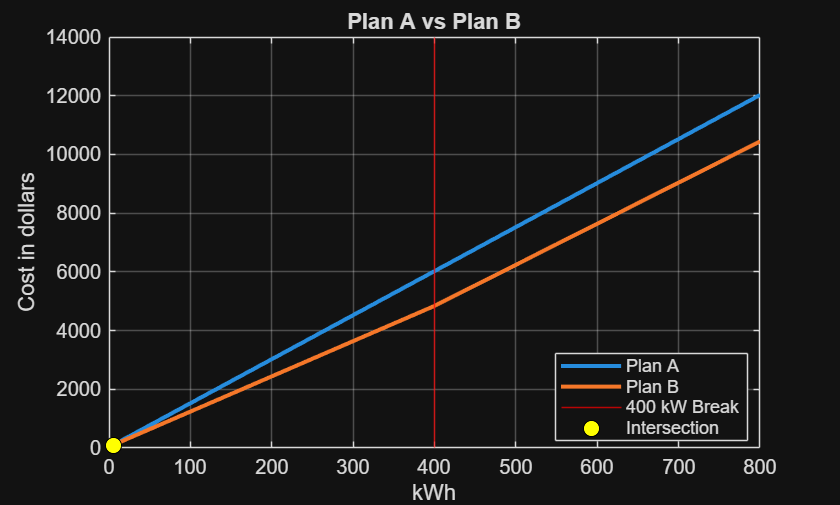

%% Clear workspace and command window
clc; clear; clear all

%% -------------------------------------------------------------
% 1. User input dialog for x‑vector parameters
% -------------------------------------------------------------
prompt = {'Enter starting value:', 'Enter step size:', 'Enter ending value:'};
dlgtitle = 'Input for x vector';
dims = [1 35];
definput = {'0','25','800'};   % default values shown in dialog

% Collect user input as strings
answer = inputdlg(prompt, dlgtitle, dims, definput);

% Convert to numeric values
startVal = str2double(answer{1});
stepVal  = str2double(answer{2});
endVal   = str2double(answer{3});

% Construct x‑vector for usage range
x = startVal:stepVal:endVal;

%% -------------------------------------------------------------
% 2. Define cost models for Plan A and Plan B
% -------------------------------------------------------------
% Plan A: single linear equation
y1 = 15*x + 25;

% Plan B: piecewise linear model
eq1 = (x <= 400);   % first region
eq2 = (x > 400);    % second region

y2 = zeros(size(x));                     % initialize
y2(eq1) = 12*x(eq1) + 40;                % cost for x <= 400
y2(eq2) = 14*x(eq2) + (40 - 2*400);      % cost for x > 400 (simplified offset)

%% -------------------------------------------------------------
% 3. Plot both plans
% -------------------------------------------------------------
plot(x, y1, 'LineWidth', 2)
hold on
plot(x, y2, 'LineWidth', 2)
grid on

% Mark the breakpoint at 400 kWh
xline(400, 'r-');

legend('Plan A', 'Plan B', '400 kW Break', 'Location', 'best');
xlabel('kWh');
ylabel('Cost in dollars');
title('Plan A vs Plan B');

%% -------------------------------------------------------------
% 4. Highlight intersection point (manually chosen as x = 5)
% -------------------------------------------------------------
x_int = 5;                      % intersection x‑value
y_int = 15*x_int + 25;          % corresponding y‑value on Plan A

% Plot intersection point
hPoint = plot(x_int, y_int, 'ko', 'MarkerSize', 8, ...
              'MarkerFaceColor', 'y', 'DisplayName', 'Intersection');


%% -------------------------------------------------------------
% 5. Build cost table for discrete usage values
% -------------------------------------------------------------
usage = (0:100:900)';   % column vector of usage values

% Plan A cost
planA = 15*usage + 25;

% Plan B cost (piecewise)
planB = zeros(size(usage));
eq1 = usage <= 400;
eq2 = usage > 400;

planB(eq1) = 12*usage(eq1) + 40;
planB(eq2) = 14*usage(eq2) - 760;   % simplified offset

% Create table
T = table(usage, planA, planB, ...
    'VariableNames', {'Usage_kW', 'PlanA_Cost', 'PlanB_Cost'});

disp(T);

    Usage_kW    PlanA_Cost    PlanB_Cost
    ________    __________    __________

        0            25            40   
      100          1525          1240   
      200          3025          2440   
      300          4525          3640   
      400          6025          4840   
      500          7525          6240   
      600          9025          7640   
      700         10525          9040   
      800         12025         10440   
      900         13525         11840   




%% -------------------------------------------------------------
% 6. Recommendation text
% -------------------------------------------------------------
fprintf('\nRECOMMENDATION:\n');


RECOMMENDATION:


fprintf('----------------------------------------\n');

----------------------------------------


fprintf('The two plans have the same cost at x = %.2f kW.\n', x_int);

The two plans have the same cost at x = 5.00 kW.


fprintf('For usage below this point, Plan A is slightly cheaper.\n');

For usage below this point, Plan A is slightly cheaper.


fprintf('For usage above this point, Plan B is cheaper.\n\n');

For usage above this point, Plan B is cheaper.




% Additional logic based on intersection location
if x_int < 0 || x_int > 400
    fprintf('However, based on realistic usage levels, Plan B is generally the better choice.\n');
else
    fprintf('Since typical usage is well above %.2f kW, customers should choose Plan B.\n', x_int);
end

Since typical usage is well above 5.00 kW, customers should choose Plan B.



fprintf('----------------------------------------\n\n');

----------------------------------------

